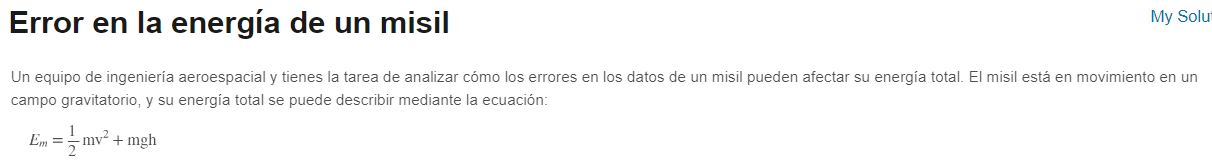

v = 1000; 
g = 9.81; 
m = 40000;
delta_h = 8;

syms h;

E = (1/2) * m * v^2 + m * g * h;

E1 = matlabFunction(E)

E1 = function_handle with value:
    @(h)h.*3.924e+5+2.0e+10


dE_h = diff(E, h)

$$dE\_h = 392400$$

errorh = 392400 * delta_h

errorh =      3139200


v = 1000; g = 9.81; delta_m = 12; delta_h = 8; %cambiar
syms m h

E = (1/2)* m * v^2 + m * g * h;

E2 = matlabFunction(E)

E2 = function_handle with value:
    @(h,m)m.*5.0e+5+h.*m.*(9.81e+2./1.0e+2)


dE_h = diff(E,h);
E_h = matlabFunction(dE_h)

E_h = function_handle with value:
    @(m)m.*(9.81e+2./1.0e+2)


dE_m = diff(E,m); 
E_m = matlabFunction(dE_m)

E_m = function_handle with value:
    @(h)h.*(9.81e+2./1.0e+2)+5.0e+5


error2 = abs(E_h(40000)) * delta_h + abs(E_m(1000)) * delta_m % cambiar

error2 =      9256920


E2(1000, 40000)

ans =      2.039240000000000e+10
